# Задание 1

km = 0.3348;
ke = 0.3348;
J = 0.0032;
R = 4.7391;
T = R*J/(ke*km)

T = 0.1353

K = ke^(-1)

K = 2.9869

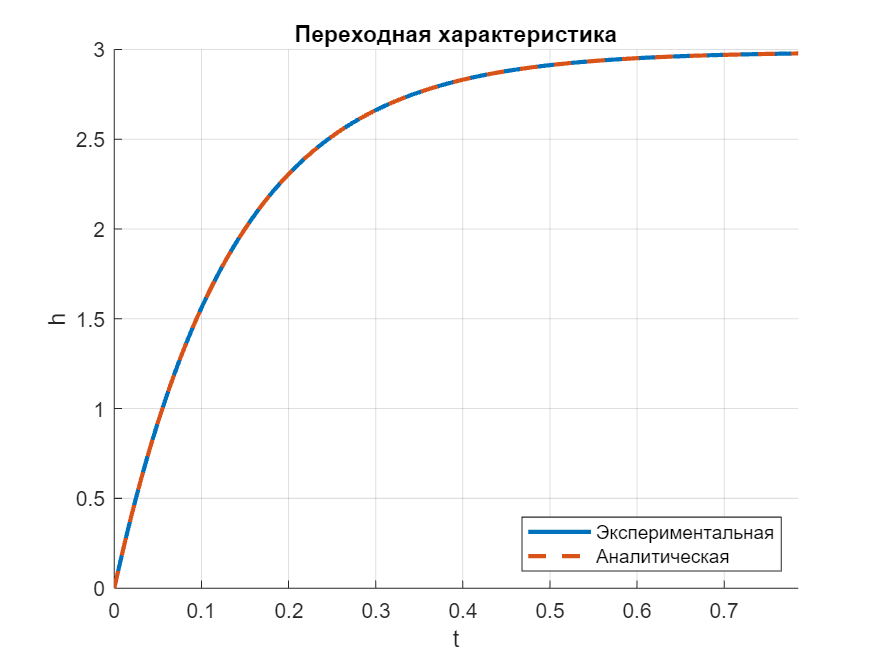

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\1_1.png



num = K;
den = [T 1];
sys = tf(num, den);

[h, t1] = step(sys);
[w, t2] = impulse(sys);

h_teor = K * (1 - exp(-t1/T));
w_teor = K / T * exp(-t1/T);

fig = figure;
hold on;
plot(t1, h, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(t1, h_teor, 'LineWidth', 2, 'LineStyle','--', 'DisplayName', 'Аналитическая');
xlim([0 max(t1)]);
title('Переходная характеристика');
xlabel('t');
ylabel('h');
legend('Location','southeast');
grid on;
hold off;
save_plot(fig, '1_1.png')

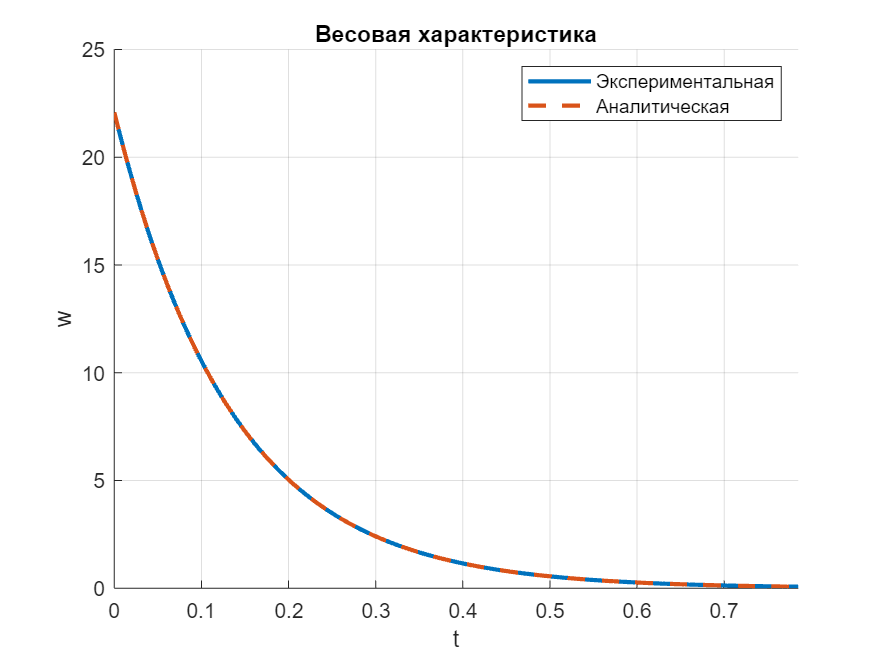

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\1_2.png




fig = figure;
hold on;
plot(t2, w, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(t2, w_teor, 'LineWidth', 2, 'LineStyle','--', 'DisplayName', 'Аналитическая');
xlim([0 max(t2)]);
title('Весовая характеристика');
xlabel('t');
ylabel('w');
legend;
grid on;
hold off;
save_plot(fig, '1_2.png')

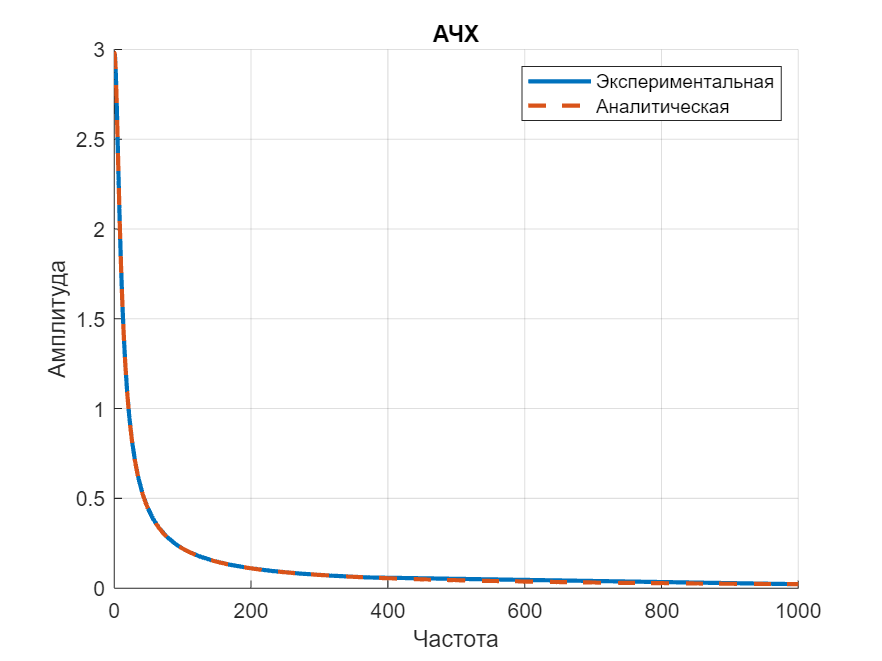

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\1_3.png




[mag, phase, omega] = bode(sys);
mag = squeeze(mag);
phase = squeeze(phase);
 
omega_teor = 0:0.001:max(omega);
mag_teor = K./(sqrt(1+omega_teor.^2 * T^2));
phase_teor = rad2deg(atan(-omega_teor.*T));

fig = figure;
hold on;
plot(omega, mag, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(omega_teor, mag_teor, 'LineWidth', 2, 'LineStyle','--', 'DisplayName', 'Аналитическая');
title('АЧХ');
xlabel('Частота');
ylabel('Амплитуда');
grid on;
legend;
save_plot(fig, '1_3.png')

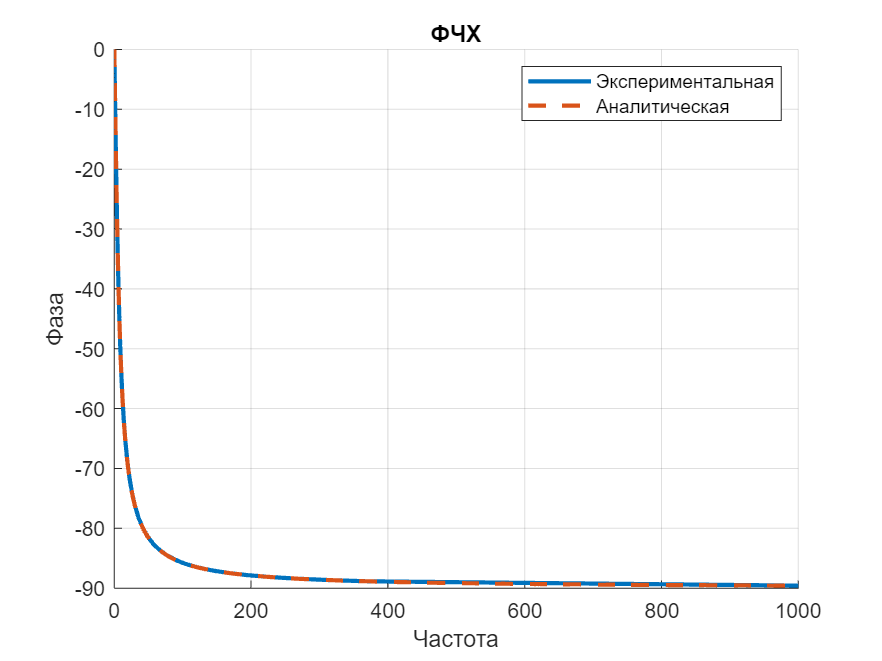

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\1_4.png



fig = figure;
hold on;
plot(omega, phase, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(omega_teor, phase_teor, 'LineWidth', 2, 'LineStyle','--', 'DisplayName', 'Аналитическая');
title('ФЧХ');
xlabel('Частота');
ylabel('Фаза');
grid on;
legend;
save_plot(fig, '1_4.png')

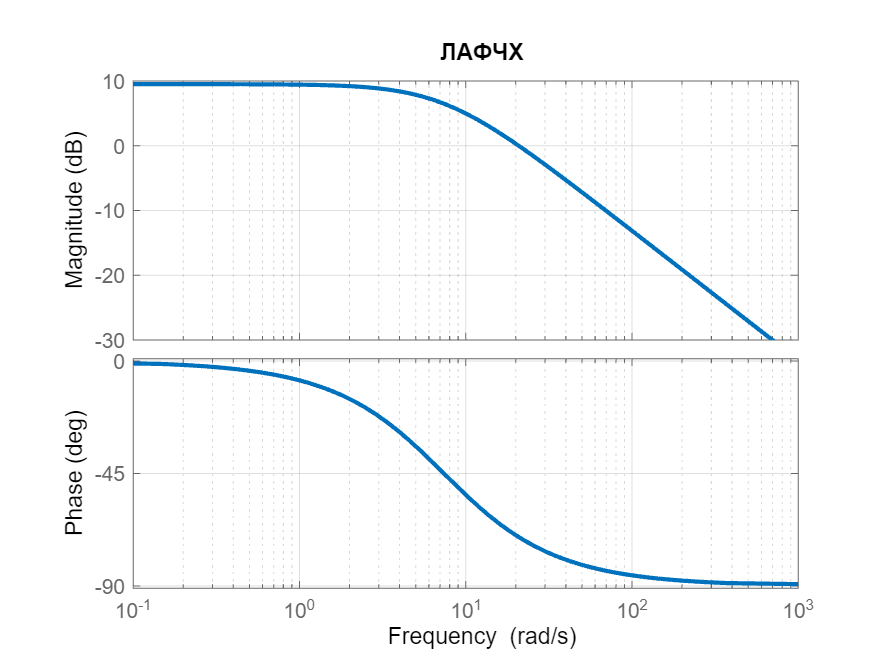

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\1_5.png



fig = figure;
bode(sys);
grid on;
l = findall(gcf, 'Type', 'line');
set(l, 'LineWidth', 2);           
title('ЛАФЧХ');
save_plot(fig, '1_5.png')

# Задание 2

km = 0.3348;
ke = 0.3348;
J = 0.0032;
R = 4.7391;
L = 1.1647;
T = sqrt(L*J / (km * ke))

T = 0.1823

xi = R/2*sqrt(J/(L*km*ke))

xi = 0.3710

K = ke^(-1)

K = 2.9869

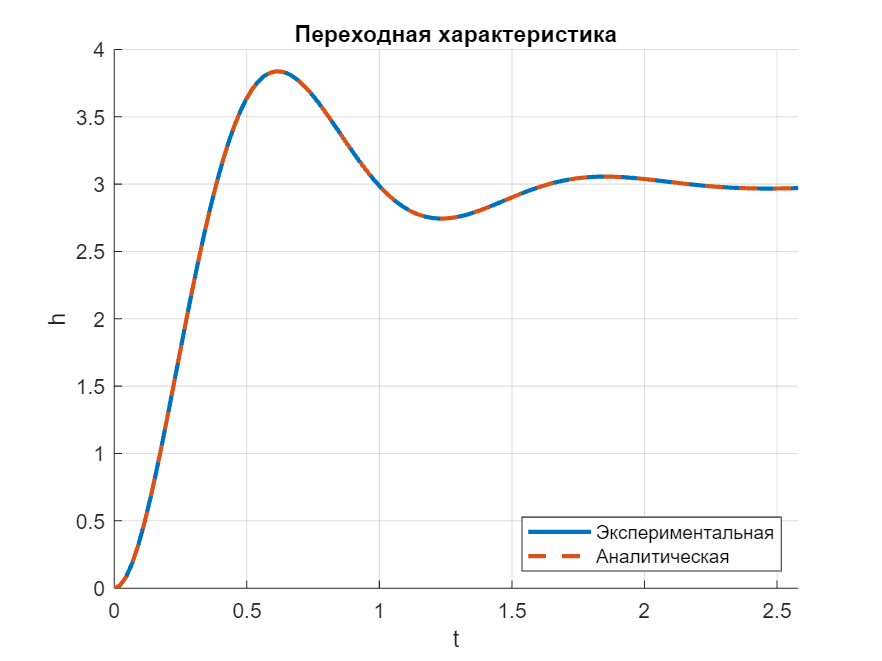

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\2_1.png



num = K;
den = [T^2 2 * xi * T 1];
sys = tf(num, den);

% Переходная характеристика
[w, t2] = impulse(sys);
[h, t1] = step(sys);

omega_0 = sqrt(1-xi.^2) / T;
alpha = xi / T;
h_teor = K .* (1 - (1 ./ sqrt(1 - xi.^2)) .* exp(-alpha .* t1) .* sin(omega_0 .* t1 + atan(sqrt(1 - xi.^2) ./ xi)));
w_teor = K .* (omega_0 + alpha^2 ./ omega_0) .* exp(-alpha .* t2) .* sin(omega_0 .* t2);

fig = figure;
hold on;
plot(t1, h, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(t1, h_teor, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
xlim([0 max(t1)]);
title('Переходная характеристика');
xlabel('t');
ylabel('h');
legend('Location', 'southeast');
grid on;
hold off;
save_plot(fig, '2_1.png');

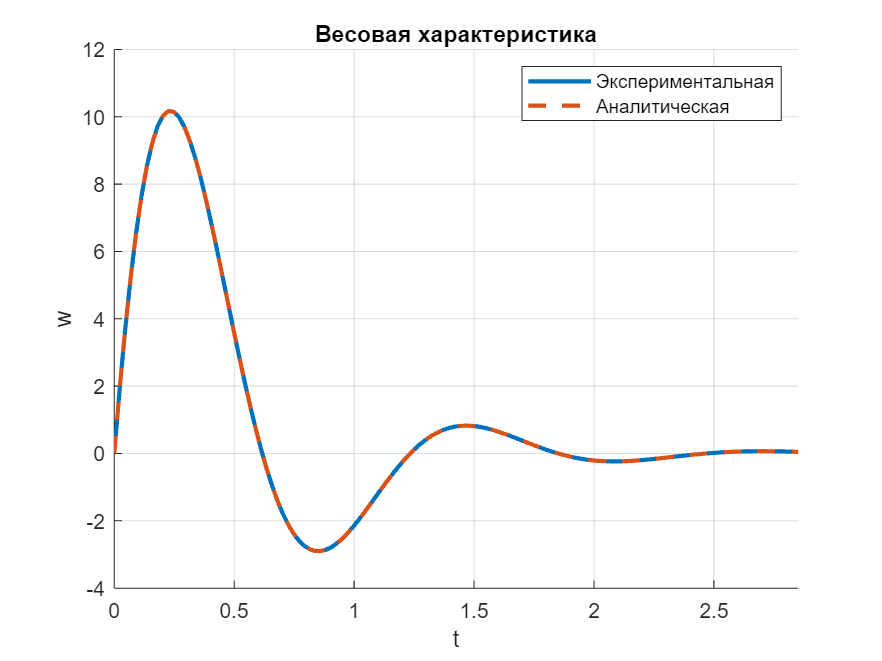

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\2_2.png



% Весовая характеристика
fig = figure;
hold on;
plot(t2, w, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(t2, w_teor, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
xlim([0 max(t2)]);
title('Весовая характеристика');
xlabel('t');
ylabel('w');
legend;
grid on;
hold off;
save_plot(fig, '2_2.png');

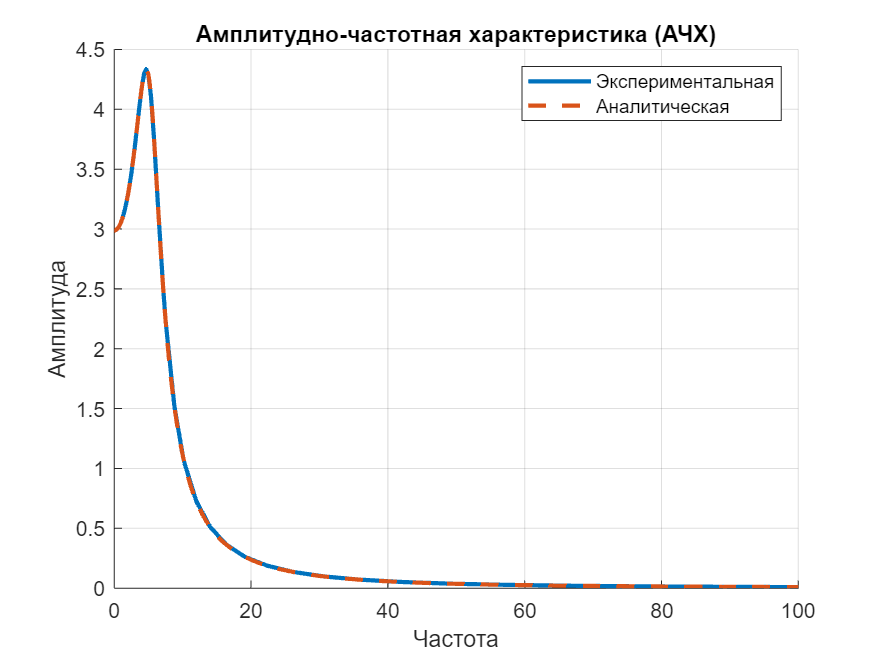

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\2_3.png



% АЧХ и ФЧХ
[mag, phase, omega] = bode(sys);
mag = squeeze(mag);
phase = squeeze(phase);

omega_teor = 0:0.001:max(omega);
mag_teor = K ./ sqrt((1 - omega_teor.^2 * T^2).^2 + (4 * xi^2 * omega_teor.^2 * T^2));
phase_teor = -atan2(2 * xi * omega_teor * T, 1 - omega_teor.^2 * T^2);

% АЧХ
fig = figure;
hold on;
plot(omega, mag, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(omega_teor, mag_teor, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Амплитудно-частотная характеристика (АЧХ)');
xlabel('Частота');
ylabel('Амплитуда');
grid on;
legend;
hold off;
save_plot(fig, '2_3.png');

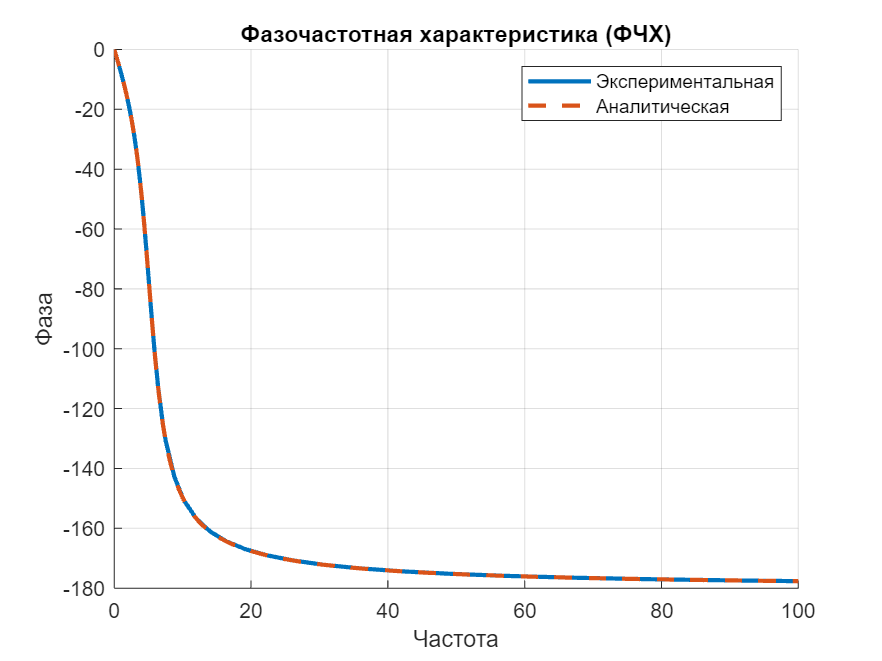

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\2_4.png



% ФЧХ
fig = figure;
hold on;
plot(omega, phase, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(omega_teor, rad2deg(phase_teor), 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Фазочастотная характеристика (ФЧХ)');
xlabel('Частота');
ylabel('Фаза');
grid on;
legend;
hold off;
save_plot(fig, '2_4.png');

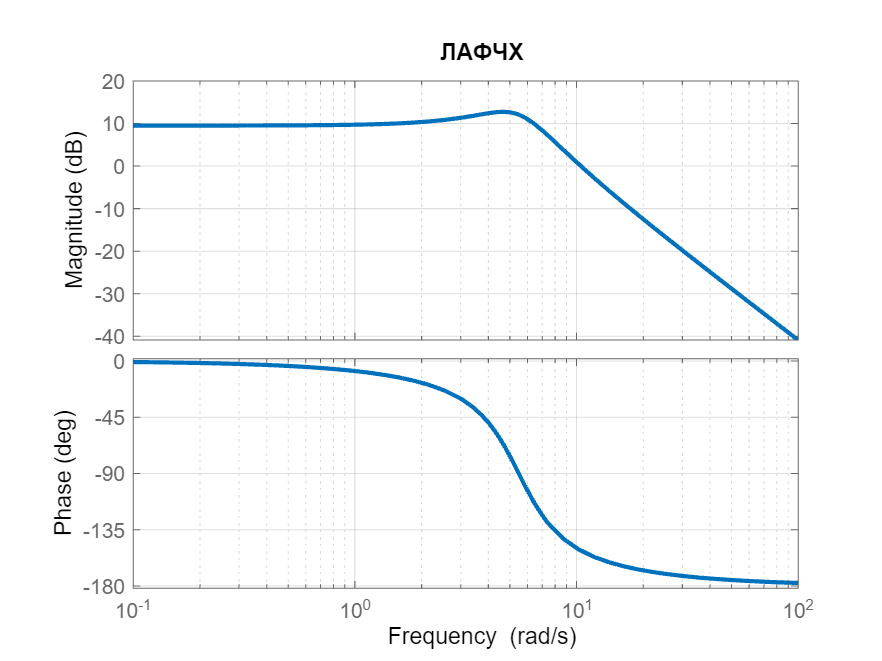

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\2_5.png



% ЛАФЧХ
fig = figure;
bode(sys);
grid on;
l = findall(gcf, 'Type', 'line');
set(l, 'LineWidth', 2);
title('ЛАФЧХ');
save_plot(fig, '2_5.png');

# Задание 3

C = 324 * 10^(-6);
K = 1 / C

K = 3.0864e+03

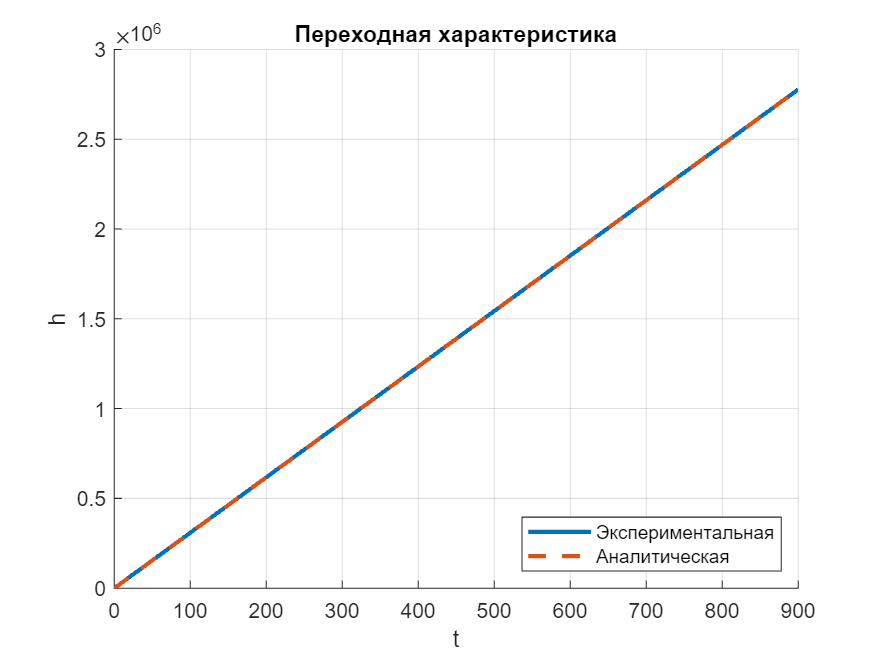

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\3_1.png



num = K;
den = [1 0];
sys = tf(num, den);

% Переходная характеристика
[w, t2] = impulse(sys);
[h, t1] = step(sys);

h_teor = K * t1;
w_teor = K * ones(size(t2)); % Весовая характеристика для идеального интегратора

fig = figure;
hold on;
plot(t1, h, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(t1, h_teor, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Переходная характеристика');
xlabel('t');
ylabel('h');
legend('Location', 'southeast');
grid on;
hold off;
save_plot(fig, '3_1.png');

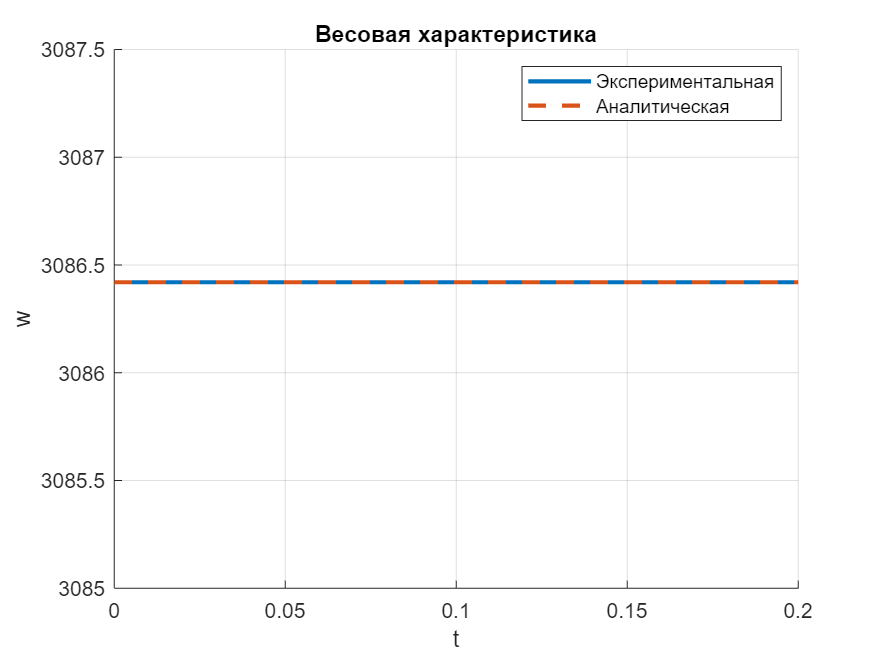

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\3_2.png



% Весовая характеристика
fig = figure;
hold on;
plot(t2, w, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(t2, w_teor, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Весовая характеристика');
xlabel('t');
ylabel('w');
legend;
grid on;
hold off;
save_plot(fig, '3_2.png');

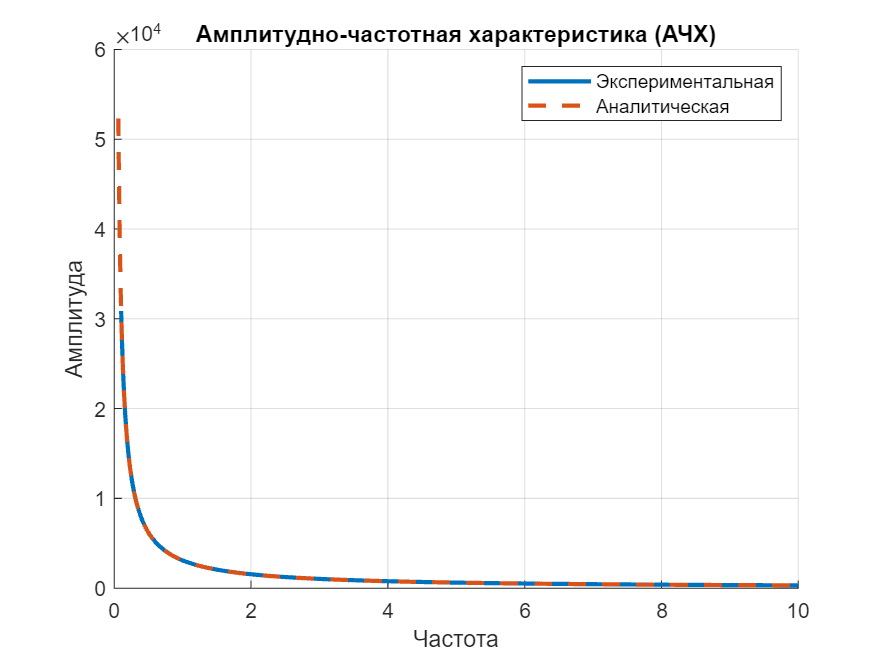

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\3_3.png



% АЧХ и ФЧХ
[mag, phase, omega] = bode(sys);
mag = squeeze(mag);
phase = squeeze(phase);

omega_teor = 0:0.001:max(omega);
mag_teor = K ./ omega_teor;
mag_teor(omega_teor == 0) = Inf; % Устранение деления на 0
phase_teor = -90 * ones(size(omega_teor));

% АЧХ
fig = figure;
hold on;
plot(omega, mag, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(omega_teor(:, 60:10000), mag_teor(:, 60:10000), 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Амплитудно-частотная характеристика (АЧХ)');
xlabel('Частота');
ylabel('Амплитуда');
grid on;
legend;
hold off;
save_plot(fig, '3_3.png');

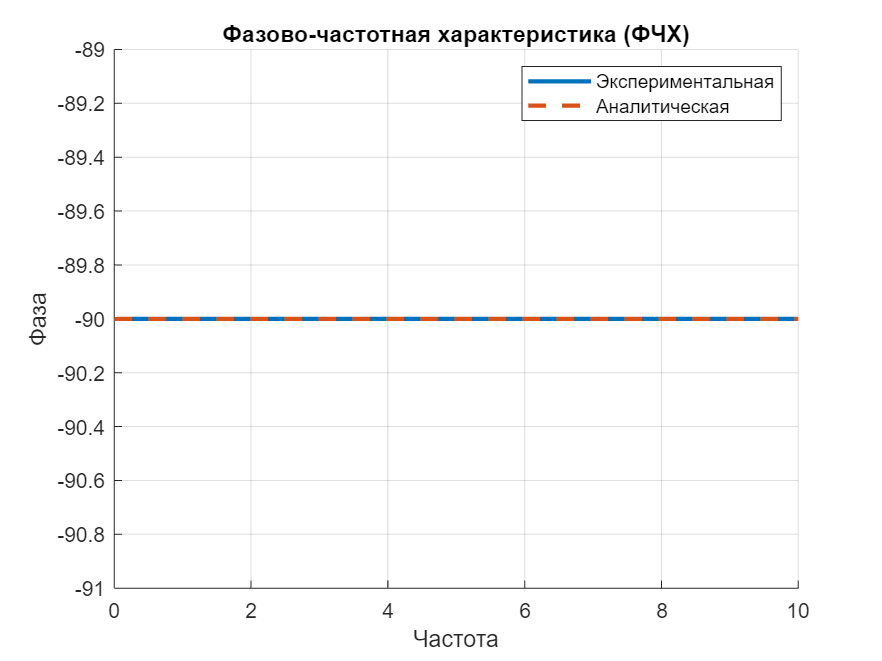

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\3_4.png



% ФЧХ
fig = figure;
hold on;
plot(omega, phase, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(omega_teor, phase_teor, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Фазово-частотная характеристика (ФЧХ)');
xlabel('Частота');
ylabel('Фаза');
grid on;
legend;
hold off;
save_plot(fig, '3_4.png');

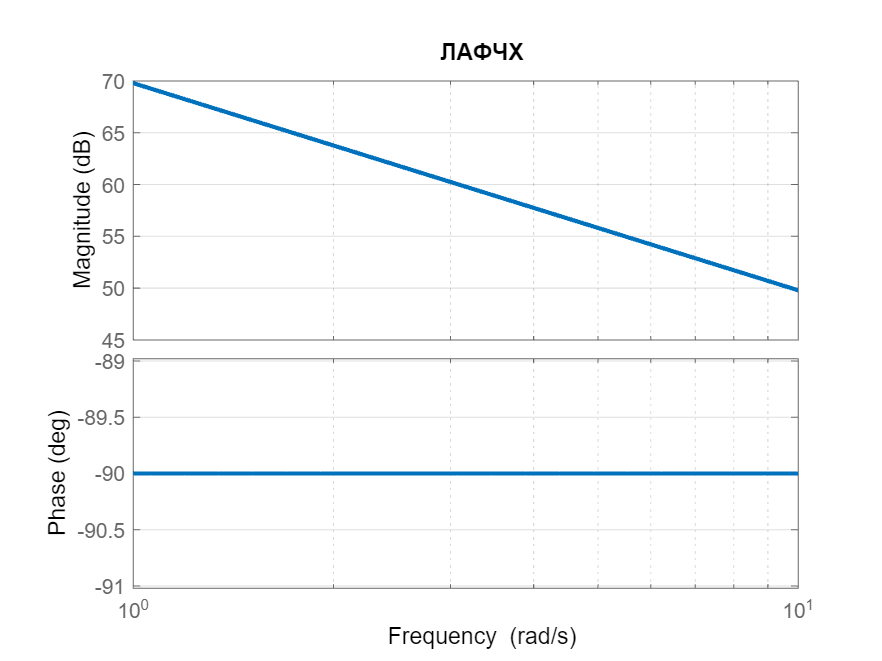

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\3_5.png



% ЛАФЧХ
fig = figure;
bode(sys);
grid on;
l = findall(gcf, 'Type', 'line');
set(l, 'LineWidth', 2);
title('ЛАФЧХ');
save_plot(fig, '3_5.png');

# Задание 4

m = 20;
k = 81;
K = 1 / k

K = 0.0123

T = sqrt(m / k)

T = 0.4969

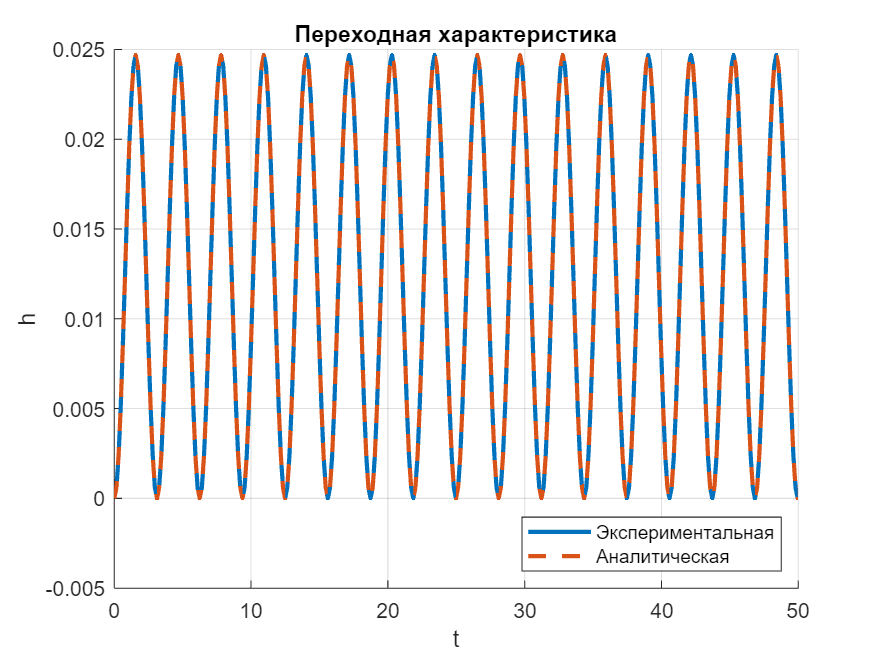

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\4_1.png



num = K;
den = [T^2 0 1];
sys = tf(num, den);

% Переходная характеристика
[w, t2] = impulse(sys);
[h, t1] = step(sys);

omega_0 = 1 ./ T;
h_teor = K .* (1 - cos(omega_0 .* t1));
w_teor = K .* omega_0 .* sin(omega_0 .* t2);

fig = figure;
hold on;
plot(t1, h, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(t1, h_teor, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Переходная характеристика');
xlabel('t');
ylabel('h');
xlim([0, 50]);
legend('Location', 'southeast');
grid on;
hold off;
save_plot(fig, '4_1.png');

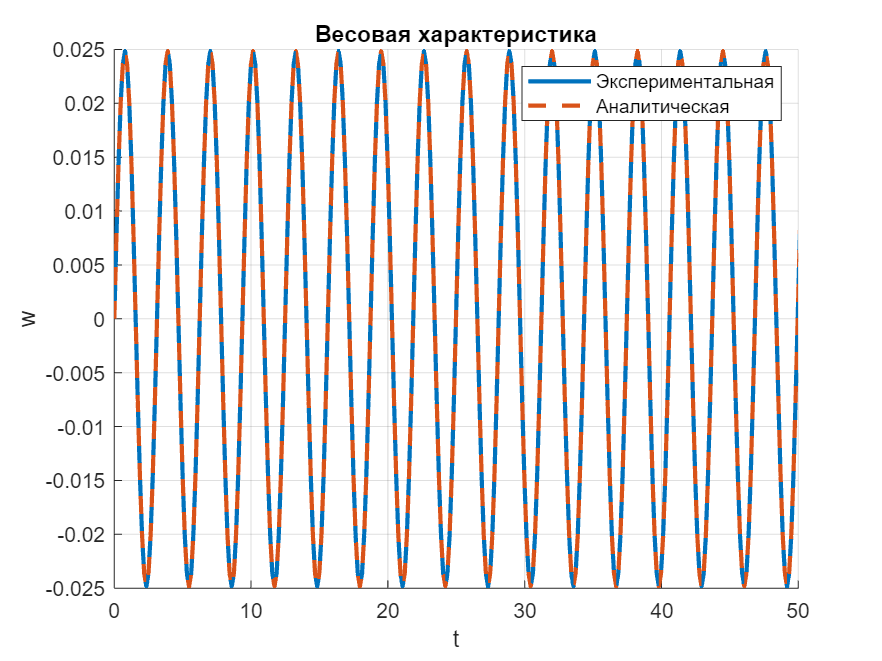

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\4_2.png



% Весовая характеристика
fig = figure;
hold on;
plot(t2, w, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(t2, w_teor, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Весовая характеристика');
xlabel('t');
ylabel('w');
xlim([0, 50]);
legend;
grid on;
hold off;
save_plot(fig, '4_2.png');

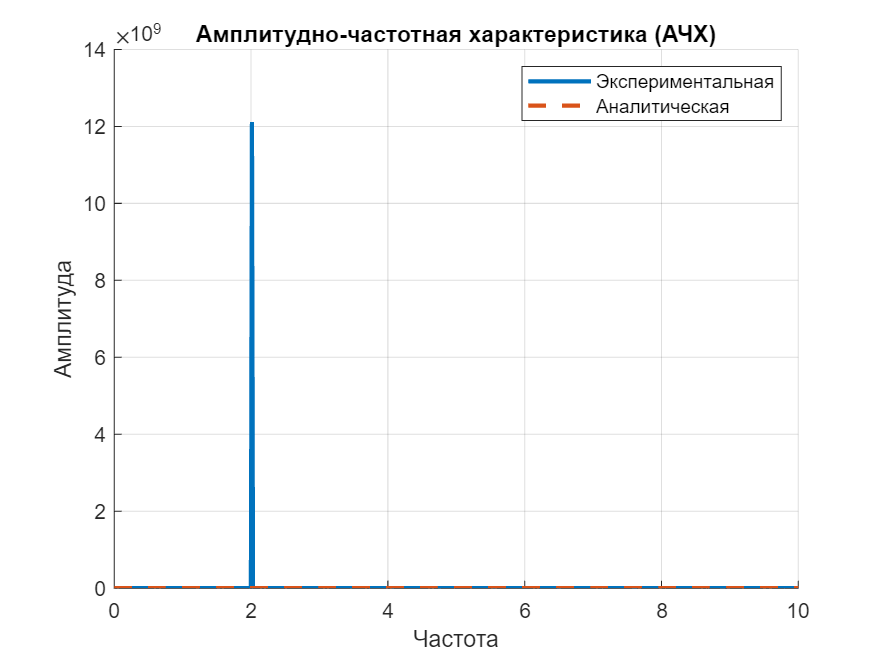

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\4_3.png



% АЧХ и ФЧХ
[mag, phase, omega] = bode(sys);
mag = squeeze(mag);
phase = squeeze(phase);

omega_teor = 0:0.001:max(omega);
mag_teor = K ./ sqrt((1 - omega_teor.^2 * T^2).^2);
phase_teor = -atan2(0, 1 - omega_teor.^2 * T^2);

% АЧХ
fig = figure;
hold on;
plot(omega, mag, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(omega_teor, mag_teor, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Амплитудно-частотная характеристика (АЧХ)');
xlabel('Частота');
ylabel('Амплитуда');
grid on;
legend;
hold off;
save_plot(fig, '4_3.png');

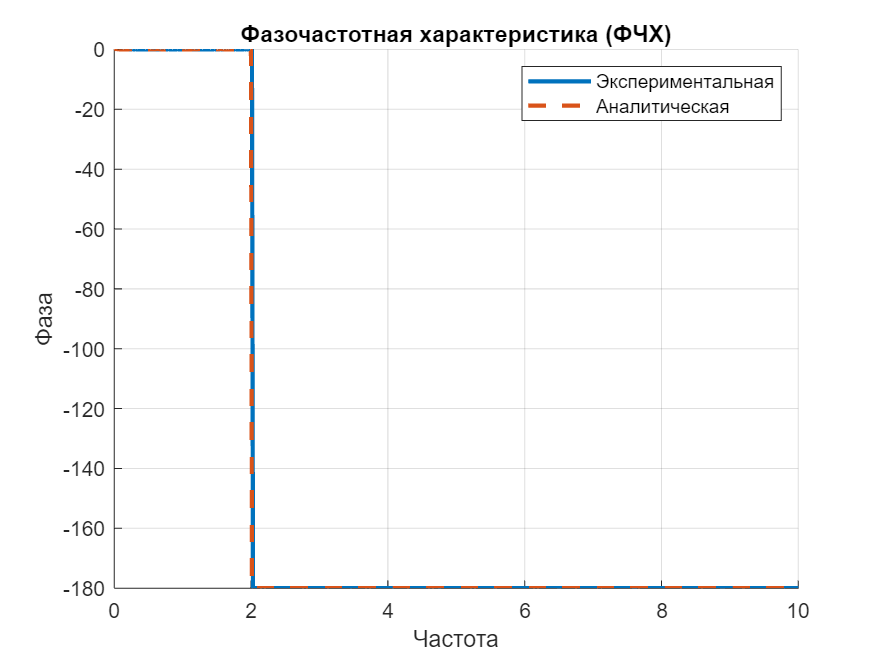

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\4_4.png



% ФЧХ
fig = figure;
hold on;
plot(omega, phase, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(omega_teor, rad2deg(phase_teor), 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Фазочастотная характеристика (ФЧХ)');
xlabel('Частота');
ylabel('Фаза');
grid on;
legend;
hold off;
save_plot(fig, '4_4.png');

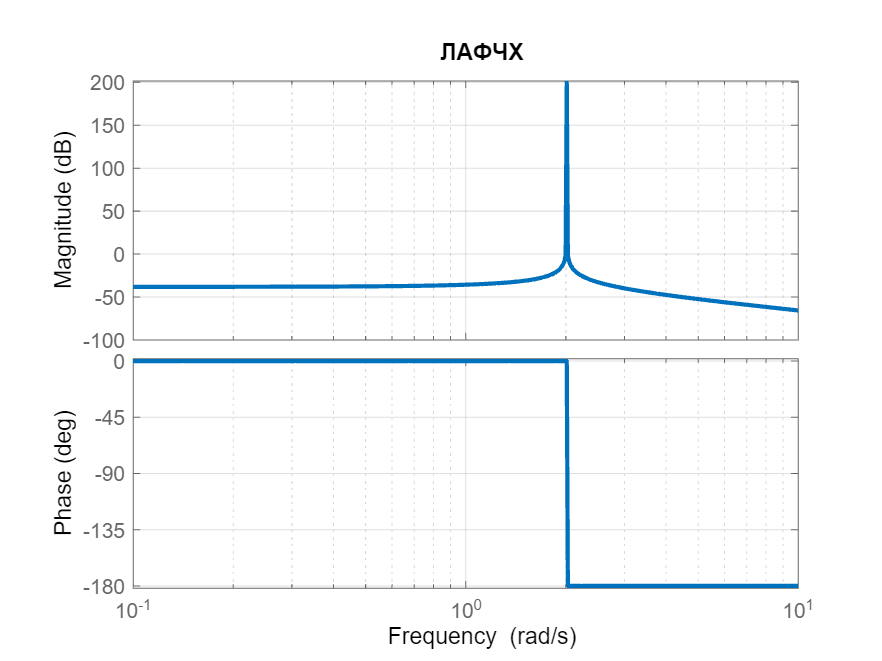

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\4_5.png



% ЛАФЧХ
fig = figure;
bode(sys);
grid on;
l = findall(gcf, 'Type', 'line');
set(l, 'LineWidth', 2);
title('ЛАФЧХ');
save_plot(fig, '4_5.png');

# Задание 5

R1 = 2425;
R2 = 21827;
C = 324 * 10^(-6);
K = R2 / R1

K = 9.0008

T = R2 * C

T = 7.0719

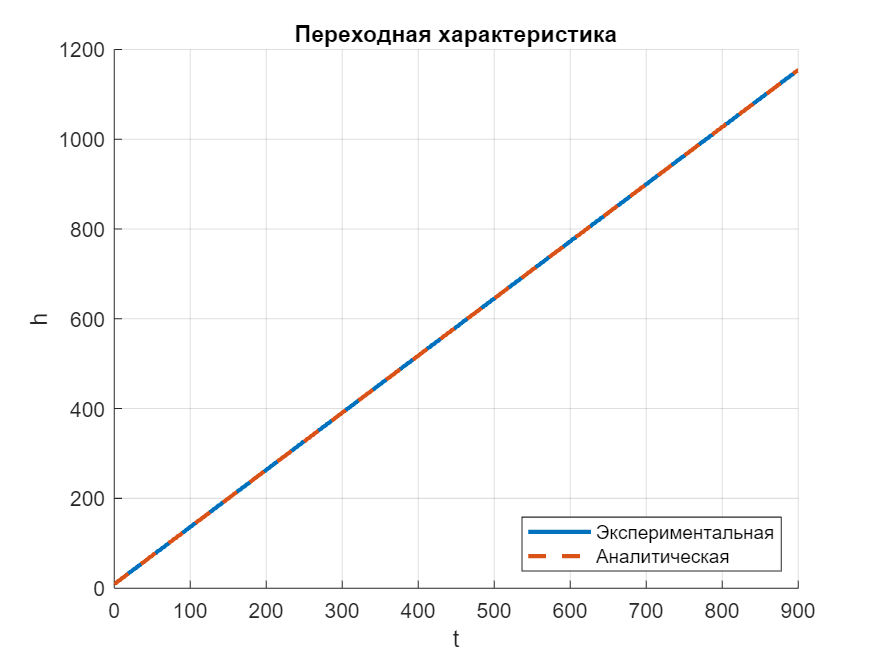

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\5_1.png



num = [K * T K];
den = [T 0];
sys = tf(num, den);

% Переходная характеристика
[w, t2] = impulse(sys);
[h, t1] = step(sys);

h_teor = K * (1 + t1 ./ T);
w_teor = (K ./ T) + 0*t2 ;

fig = figure;
hold on;
plot(t1, h, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(t1, h_teor, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Переходная характеристика');
xlabel('t');
ylabel('h');
legend('Location', 'southeast');
grid on;
hold off;
save_plot(fig, '5_1.png');

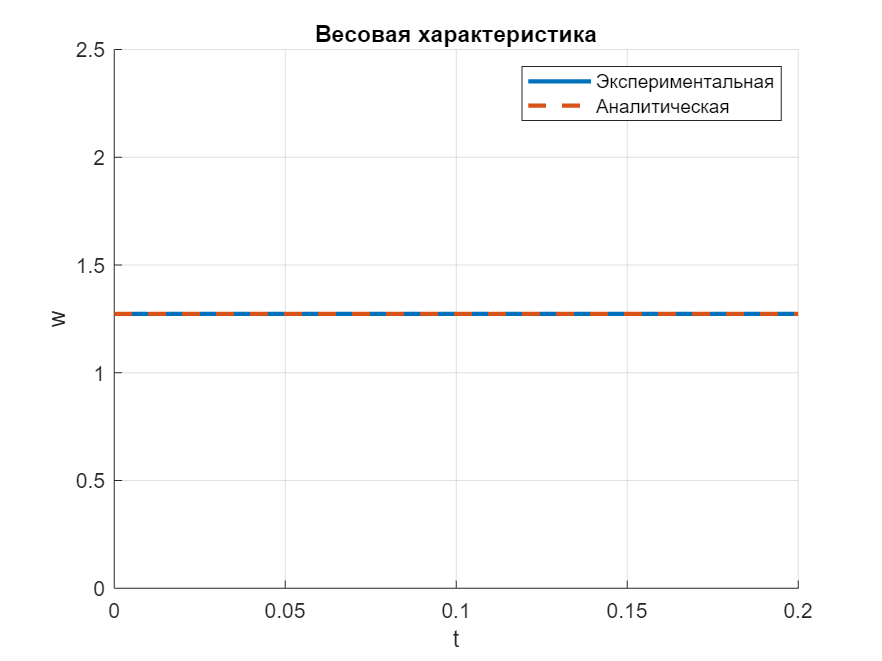

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\5_2.png



% Весовая характеристика
fig = figure;
hold on;
plot(t2, w, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(t2, w_teor, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Весовая характеристика');
xlabel('t');
ylabel('w');
legend;
grid on;
hold off;
save_plot(fig, '5_2.png');

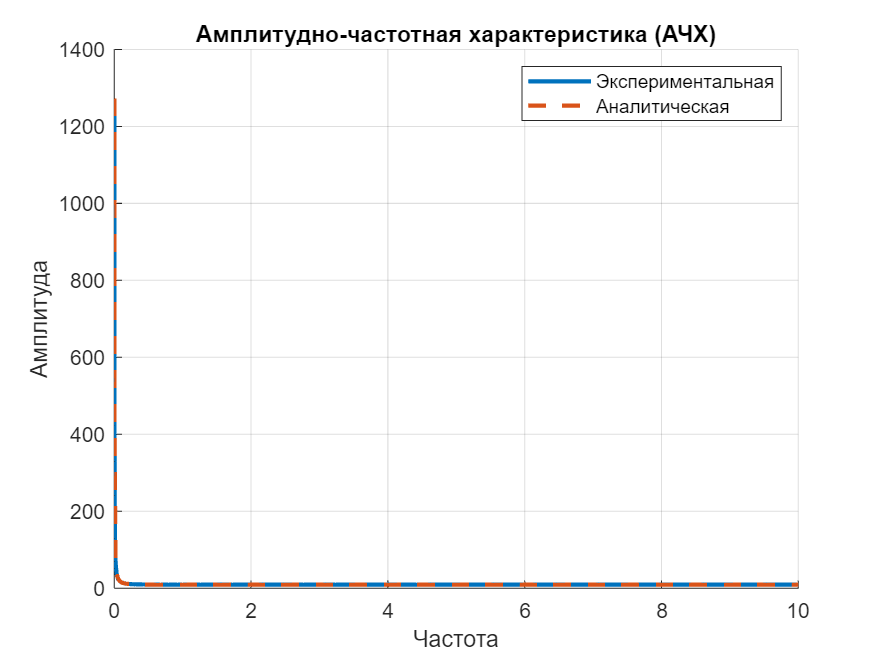

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\5_3.png



% АЧХ и ФЧХ
[mag, phase, omega] = bode(sys);
mag = squeeze(mag);
phase = squeeze(phase);

omega_teor = 0:0.001:max(omega);
mag_teor = K * sqrt(omega_teor.^2 * T^2 + 1) ./ (T * omega_teor);
mag_teor(omega_teor == 0) = Inf; % Устранение деления на 0
phase_teor = -atan(1 ./ (T * omega_teor));

% АЧХ
fig = figure;
hold on;
plot(omega, mag, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(omega_teor, mag_teor, 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Амплитудно-частотная характеристика (АЧХ)');
xlabel('Частота');
ylabel('Амплитуда');
grid on;
legend;
hold off;
save_plot(fig, '5_3.png');

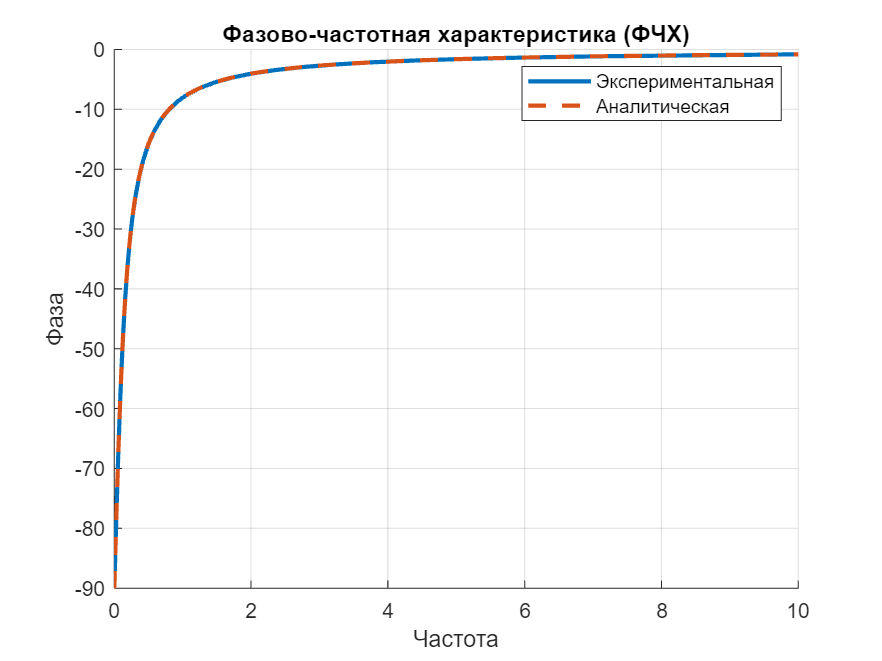

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\5_4.png



% ФЧХ
fig = figure;
hold on;
plot(omega, phase, 'LineWidth', 2, 'DisplayName', 'Экспериментальная');
plot(omega_teor, rad2deg(phase_teor), 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Аналитическая');
title('Фазово-частотная характеристика (ФЧХ)');
xlabel('Частота');
ylabel('Фаза');
grid on;
legend;
hold off;
save_plot(fig, '5_4.png');

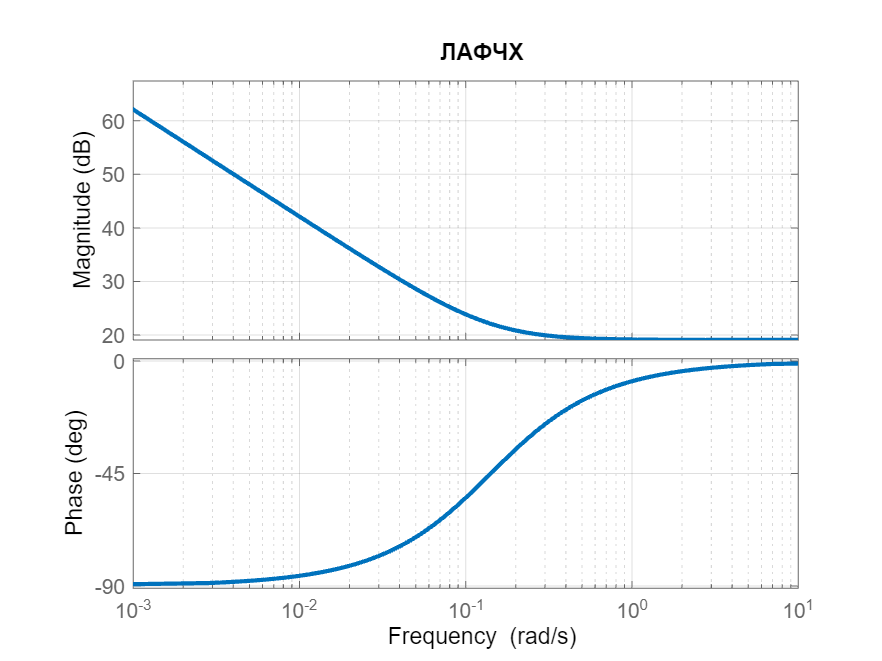

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab5\report\images\5_5.png



% ЛАФЧХ
fig = figure;
bode(sys);
grid on;
l = findall(gcf, 'Type', 'line');
set(l, 'LineWidth', 2);
title('ЛАФЧХ');
save_plot(fig, '5_5.png');


% bp = bodeplot(sys);
% setoptions(bp, 'FreqUnits', 'Hz', 'FreqScale', 'linear');

function save_plot(fig, save_filename)
    save_path = 'C:\Users\vasil\Desktop\lsau\lab5\report\images'; % Замените на свой путь
    
    % Полный путь к файлу
    full_save_path = fullfile(save_path, save_filename);
    
    % Сохранение графика
    exportgraphics(fig, full_save_path, "Resolution", 600); 
    disp(['График сохранен по пути: ' full_save_path]);
end